%% kinematic simulation 3 two-wheeled mobile robot with Control
clear all 
clc
close all 


%% simulation parameter

total_time = 5;  % (seconds)
dt = 0.1; % step sizes
time_stamp = total_time/dt; % simulation time
i = 1; % to start while loop


%% mobile robot parameter and initial contitions
theta_i = 0;
v_i = [1; 1; 1];
w_i = [1; 1; 1];
v_r = 1;
w_r = pi;
%% Robot 1
x_pos_1 = zeros(3, time_stamp);
point_1 = [0;0;0];

%% Robot 2
x_pos_2 = zeros(3, time_stamp);
point_2 = [1;1;0];

%% Robot 3
x_pos_3 = zeros(3, time_stamp);
point_3 = [2;2;0];

%% Combine Robot Parameters
x_pos(:,:,1) = x_pos_1;
x_pos(:,:,2) = x_pos_2;
x_pos(:,:,3) = x_pos_3;

point(:,:,1) = point_1;
point(:,:,2) = point_2;
point(:,:,3) = point_3;
er = zeros(3, 3);
position_r = [4;4;pi];


%% loop starts here
while i <= time_stamp
    for j = 1:3
        x_pos(:,i,j) = point(:,:,j);
        q_dot(:,:,j) = model(point(3,j),v_i(j),w_i(j));
        point(1:2,j) = point(1:2,j) + q_dot(1:2,j) * dt;
        point(3,j) = point(3,j) + q_dot(3,j) * dt;
        e = error_function(position_r(1),position_r(2),position_r(3),point(1,:,j),point(2,:,j),point(3,:,j));
        er(:,j) = e;
        v_i(j) = v_r * cos(er(3,j)) + 2 * er(1,j);
        w_i(j) = w_r + (-2 * er(2,j) + (2*er(3,j)));
        %disp(point)
    end
    time(i) = i/10;
    i = i + 1;
end

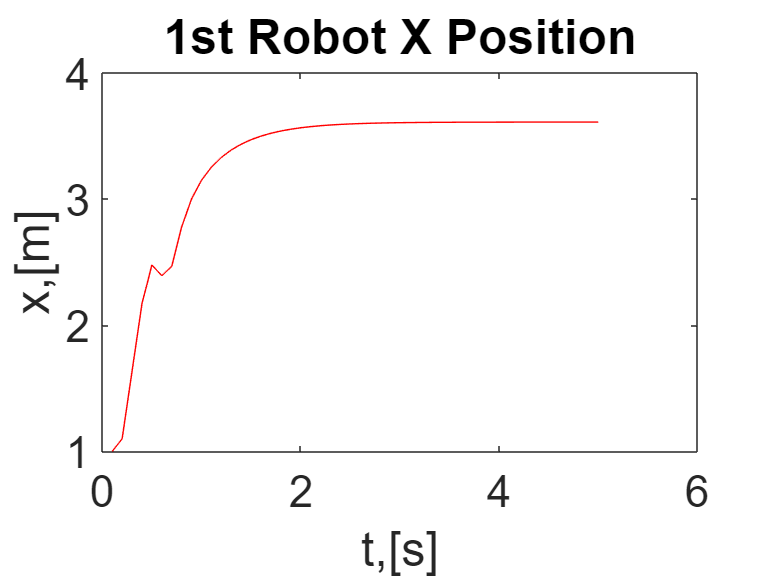


% plotting functions
figure
plot(time, x_pos(1,:,2),'r');
set(gca, 'fontsize',24)
xlabel('t,[s]');
ylabel('x,[m]');
title("1st Robot X Position")

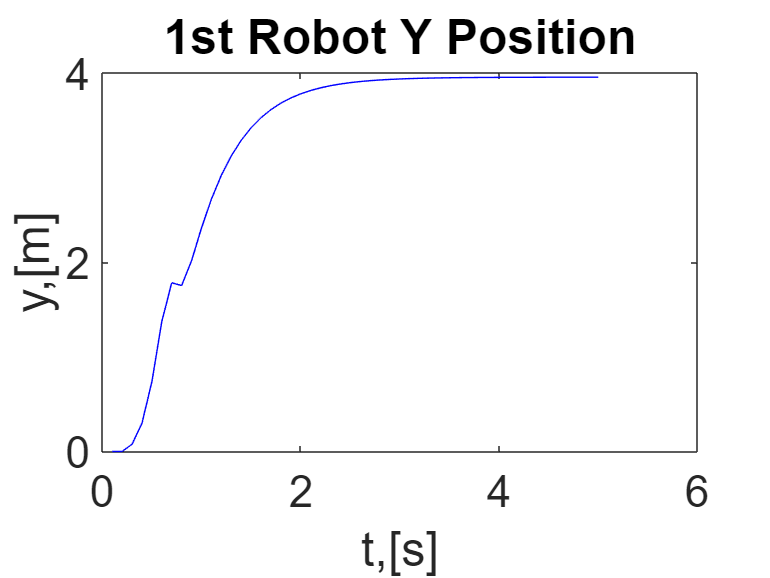


%
figure
plot(time, x_pos(2,:,1),'b-');
set(gca,'fontsize',24);
xlabel('t,[s]');
ylabel('y,[m]');
title("1st Robot Y Position")

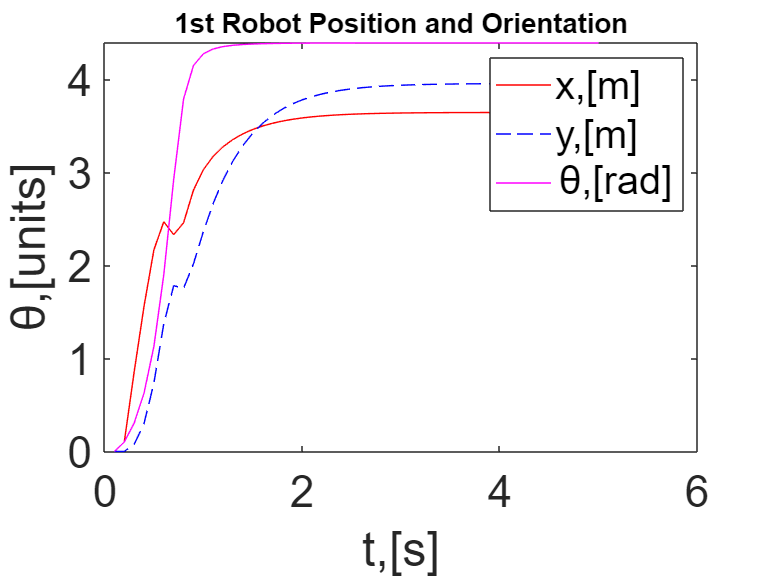


figure
plot(time, x_pos(1,:,1),'r');
hold on
plot(time, x_pos(2,:,1),'b--');
plot(time, x_pos(3,:,1),'m');
legend('x,[m]','y,[m]','\theta,[rad]');
set(gca,'fontsize',24)
xlabel('t,[s]');
ylabel('\theta,[units]');
title("1st Robot Position and Orientation",'FontSize',15)

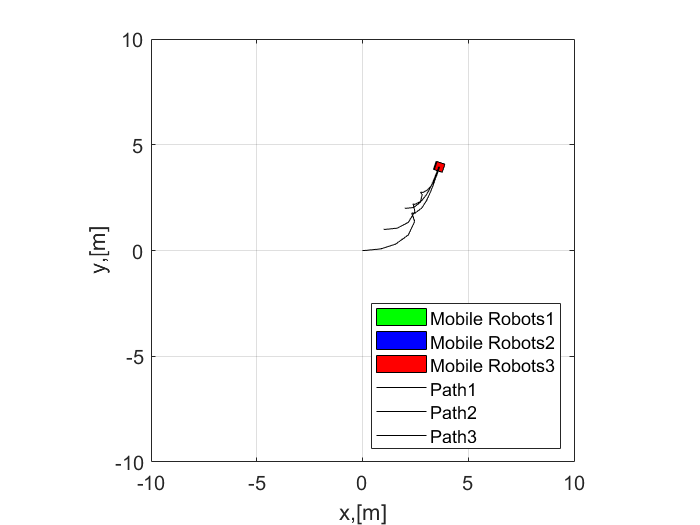


%% Animation (mobile robot motion animation)
l = 0.4; % length of the mobile robot
w = 0.4; % width of the mobile robot
% Mobile robot cooridinates
box_v = [-l/2,l/2,l/2,-l/2,-l/2;
         -w/2,-w/2,w/2,w/2,-w/2;];   
figure
for i = 1:5:length(time)
    theta = x_pos(3,i,1);
    R_theta = [cos(theta), -sin(theta);
               sin(theta), cos(theta);]; % rotation matrix
    v_pos = R_theta*box_v;
    fill(v_pos(1,:)+x_pos(1,i,1),v_pos(2,:)+x_pos(2,i,1),'g','DisplayName','Mobile Robots1');
    hold on
    fill(v_pos(1,:)+x_pos(1,i,2),v_pos(2,:)+x_pos(2,i,2),'b','DisplayName','Mobile Robots2');
    hold on
    fill(v_pos(1,:)+x_pos(1,i,3),v_pos(2,:)+x_pos(2,i,3),'r','DisplayName','Mobile Robots3');
    hold on, grid on
    axis([-10 10 -10 10]), axis square
    plot(x_pos(1,1:i,1),x_pos(2,1:i,1),'black','DisplayName','Path1');
    plot(x_pos(1,1:i,2),x_pos(2,1:i,2),'black','DisplayName','Path2');  
    plot(x_pos(1,1:i,3),x_pos(2,1:i,3),'black','DisplayName','Path3');  
    set(gca, 'fontsize',12)
    xlabel('x,[m]'); ylabel('y,[m]');
    pause(0.01)
    grid on
    hold off
end % animation ends here
legend('Location',"southeast")